clc;
clear all;

%-----Geometry,Number of simulations------%
d = 10;
N = 1000;
a11 = 250*(d/10);
a12= 100*(d/10);

%-----Mesh grid boundary definition--------%
xms=a11/2 - 2*(d);
xmf=a11/2 + 2*(d);
yms=a12/2 - 2*(d);
ymf=a12/2 + 2*(d);

%----------------Grid size----------------%
g = 0.085 ;
xq1=xms:g:xmf;
xq = xq1';
yq1=yms:g:ymf;
yq = yq1';

%-----Mesh gird around the hole----------%
[K1,K2] = meshgrid(xq, yq);
a= size(xq1,2);
b= size(yq1,2);
for k = 0:b
    for j=0:a
       e=((k*g)-2*d)^2+((j*g)-2*d)^2-(.5*d)^2;
 
        if e<0
          
            K1(j,k)=  NaN;
            K2(j,k)=  NaN;
        end
    end
end
 zz1=0;
 zz2= 0;

%----Importing files from abaqus---------%
for i =1:N
    fx =[ 'C:\Temp\final1\jjx' num2str(i) '.txt'];
    fy =[ 'C:\Temp\final1\jjy' num2str(i) '.txt'];
    fu =[ 'C:\Temp\final1\jju1' num2str(i) '.txt'];
    fv =[ 'C:\Temp\final1\jju2' num2str(i) '.txt'];
    
x = textfile(fx);
y = textfile(fy);
z1 = textfile(fu);
z2 = textfile(fv);
U1 = griddata(x,y,z1,K1,K2);
U2 = griddata(x,y,z2,K1,K2);


zz1 = U1+zz1;
zz2 = U2+zz2;
i  ;
end


%--------Averaging the displacements-------%
zpk1 = (zz1)./N;
zpk2 = (zz2)./N;


xlswrite('zpk1.xlsx',zpk1)
xlswrite('zpk2.xlsx',zpk2)

%------Creating a strain matrix-----------%
E = zeros(2*(size(K1,1)-1),2*(size(K1,1)-1))

E =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

for j = 1: (size(K1,1)-1)
    for i = 1: (size(K1,1)-1)
         v = [zpk1(j,i);zpk2(j,i);zpk1(j,i+1);zpk2(j,i+1);zpk1(j+1,i+1);zpk2(j+1,i+1);zpk1(j+1,i);zpk2(j+1,i)];
         e1= strain1(v);
         e2= strain2(v);
         e3= strain3(v);
         e4= strain4(v);
         E((2*j-1),(2*i-1)) = e1(1);
         E((2*j-1),2*i) = e2(1);
         E(2*j,(2*i-1)) = e4(1);
         E(2*j,2*i) = e3(1);
    end
end

  ST = E/(1.5*(10)^(-4))

ST =     0.8724    0.8724    0.8647    0.8647    0.8563    0.8563    0.8540    0.8540    0.8528    0.8528    0.8644    0.8644    0.9317    0.9317    0.9231    0.9231    0.9137    0.9137    0.9118    0.9118    0.9094    0.9094    0.9086    0.9086    0.9109    0.9109    0.9106    0.9106    0.9086    0.9086    0.9071    0.9071    0.9059    0.9059    0.8812    0.8812    0.8356    0.8356    0.8345    0.8345    0.8323    0.8323    0.8319    0.8319    0.8311    0.8311    0.8071    0.8071    0.7801    0.7801
    0.8695    0.8695    0.8533    0.8533    0.8571    0.8571    0.8547    0.8547    0.8540    0.8540    0.8755    0.8755    0.9245    0.9245    0.9099    0.9099    0.9103    0.9103    0.9090    0.9090    0.9071    0.9071    0.9073    0.9073    0.9100    0.9100    0.9101    0.9101    0.9087    0.9087    0.9071    0.9071    0.9062    0.9062    0.8815    0.8815    0.8358    0.8358    0.8347    0.8347    0.8326    0.8326    0.8316    0.8316    0.8317    0.8317    0.8073    0.8073    0.7807    

  su = round(4*d/g)+1   ;
  r = E((((su-1)- round(d/g)):-1:1),(su-1));
  p = E((((su-1)- round(d/g)):-1:1),(su));
  st = (p+r)./(1.5*(10)^(-4));
  m = g*(size(r)-1);
  H = 0:g:(m);
  h = H./10;
  
  writematrix(st)
  type 'st.txt'

NaN
NaN
NaN
4.04131330640115
3.85577190305555
3.74470609887823
3.62681008222791
3.55014973442178
3.45860578593987
3.39695297252209
3.32005830231706
3.26611803980163
3.1956451722409
3.14804198860758
3.08846053988004
3.04626921188236
2.99058180888141
2.95175196087913
2.9013542462877
2.86651893961953
2.82174482649627
2.78880676508158
2.74359242091709
2.71424778191504
2.67929108139615
2.65444102989538
2.62150612714344
2.59889577830463
2.57005805925207
2.54898762294661
2.52025983947505
2.50050073522341
2.47524564196745
2.45731889004271
2.43359718622559
2.41666500225668
2.39412711918764
2.37863666365083
2.35885383516091
2.34457911537376
2.32536268414136
2.31220137651291
2.29546044661034
2.28391779020202
2.26912359634276
2.25699491901559
2.23865295018842
2.2286721241344
2.21974596908051
2.21206781759461
2.20001687268079
2.1916383171964
2.18079862283281
2.17311141451499
2.16294926518591
2.15541008506368
2.14497481125141
2.13796878218631
2.12926322863342
2.12208542880009
2.11118086852177
2.1049

  writematrix(h)
  type 'h.txt'

0,0.0085,0.017,0.0255,0.034,0.0425,0.051,0.0595,0.068,0.0765,0.085,0.0935,0.102,0.1105,0.119,0.1275,0.136,0.1445,0.153,0.1615,0.17,0.1785,0.187,0.1955,0.204,0.2125,0.221,0.2295,0.238,0.2465,0.255,0.2635,0.272,0.2805,0.289,0.2975,0.306,0.3145,0.323,0.3315,0.34,0.3485,0.357,0.3655,0.374,0.3825,0.391,0.3995,0.408,0.4165,0.425,0.4335,0.442,0.4505,0.459,0.4675,0.476,0.4845,0.493,0.5015,0.51,0.5185,0.527,0.5355,0.544,0.5525,0.561,0.5695,0.578,0.5865,0.595,0.6035,0.612,0.6205,0.629,0.6375,0.646,0.6545,0.663,0.6715,0.68,0.6885,0.697,0.7055,0.714,0.7225,0.731,0.7395,0.748,0.7565,0.765,0.7735,0.782,0.7905,0.799,0.8075,0.816,0.8245,0.833,0.8415,0.85,0.8585,0.867,0.8755,0.884,0.8925,0.901,0.9095,0.918,0.9265,0.935,0.9435,0.952,0.9605,0.969,0.9775,0.986,0.9945,1.003,1.0115,1.02,1.0285,1.037,1.0455,1.054,1.0625,1.071,1.0795,1.088,1.0965,1.105,1.1135,1.122,1.1305,1.139,1.1475,1.156,1.1645,1.173,1.1815,1.19,1.1985,1.207,1.2155,1.224,1.2325,1.241,1.2495,1.258,1.2665,1.275,1.2835,1.292,1.3005,1.309,1.31

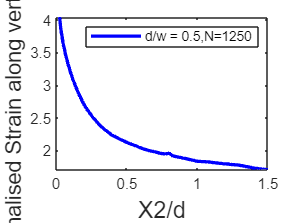

     
  plot(h,st,'LineWidth',2,'Color','b')
  xlim([0 1.5])
  xlabel("X2/d",'fontsize',14)
  ylabel("Normalised Strain along vertical path", 'fontsize',13)
  legend('d/w = 0.5,N=1250')

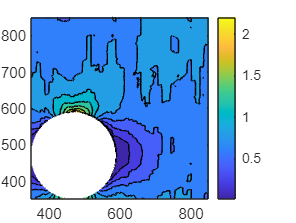


 

contourf(ST);
colorbar;
xlim([350 850]);
ylim([350 850]);

sa

Unrecognized function or variable 'sa'.

function E1 = strain1(v)
B1 = [1 0 0 0;0 0 0 1;0 1 1 0];
%% for node 1 
x1=-1/sqrt(3);eta1=-1/sqrt(3);
B21 = B2();
B31 = B3(x1,eta1);
B12 = B1*B21;
B = B12*B31;
E1 =B*v; 
end 
function E1 = strain2(v)
B1 = [1 0 0 0;0 0 0 1;0 1 1 0];
%% for node 1 
x1=1/sqrt(3);eta1=-1/sqrt(3);
B21 = B2();
B31 = B3(x1,eta1);
B12 = B1*B21;
B = B12*B31;
E1 =B*v; 
end 
function E1 = strain3(v)
B1 = [1 0 0 0;0 0 0 1;0 1 1 0];
%% for node 1 
x1=1/sqrt(3);eta1=1/sqrt(3);
B21 = B2();
B31 = B3(x1,eta1);
B12 = B1*B21;
B = B12*B31;
E1 =B*v; 
end 
function E1 = strain4(v)
B1 = [1 0 0 0;0 0 0 1;0 1 1 0];
%% for node 4
x1=-1/sqrt(3);eta1=1/sqrt(3);
B21 = B2();
B31 = B3(x1,eta1);
B12 = B1*B21;
B = B12*B31;
E1 =B*v; 
end 


function B21 = B2()
B21 = [0.05/0.0025 0 0 0;0 0.05/0.0025 0 0;0 0 0.05/0.0025 0;0 0 0 0.05/0.0025];
end 
function B31 = B3(x1,eta1)
B31 = [-(1-eta1)*0.25 0 (1-eta1)*0.25 0 (1+eta1)*0.25 0 -(1+eta1)*0.25 0;...
       -(1-x1)*0.25 0  -(1+x1)*0.25 0 (1+x1)*0.25 0 (1-x1)*0.25 0;...
       0 -(1-eta1)*0.25 0 (1-eta1)*0.25 0 (1+eta1)*0.25 0 -(1+eta1)*0.25;...
       0  -(1-x1)*0.25 0  -(1+x1)*0.25 0 (1+x1)*0.25 0 (1-x1)*0.25];
end
function value = textfile(path)
    fileID = fopen(path,'r'); 
    value= fscanf(fileID,'%f');
    fclose(fileID);
end





